# Generating All the Figures 

Figure list: 

Fig1: VNA Data (not here) 

Fig2A: Clinic output (both hemisphere)

Fig2B: 3 trial comparison example per contact 

Fig2C: All pt water fall plot w averaged runs across contacts and pts 

Fig3: Histogram across frequencies, one pt example 

Fig4: all runs all contact all patients across frequencies 

## Fig2A

The highest beta comes from contact pair 02


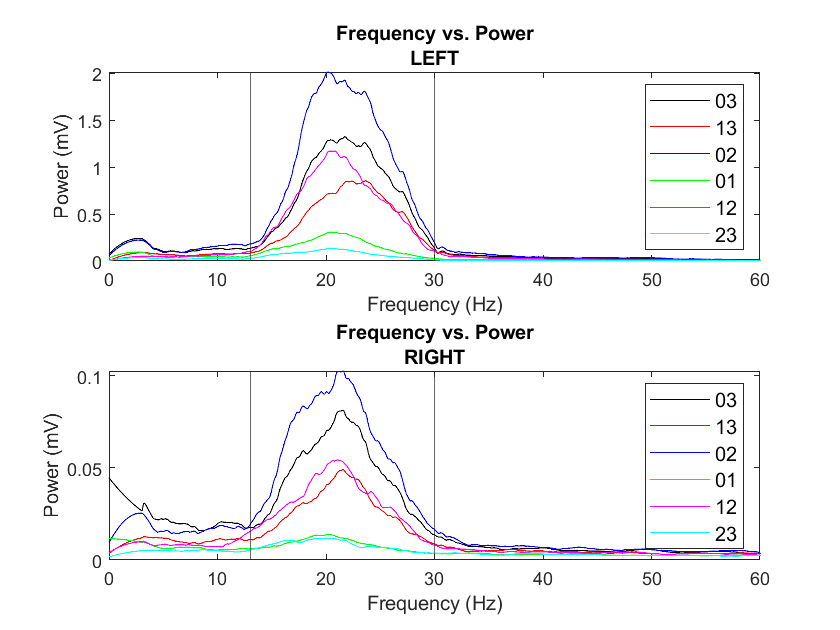

The highest beta comes from contact pair 02


%%
clear
cd('C:\Users\sydne\Documents\github\perceive')
%jsonFiles = 'Report_Json_Session_Report_20210604T094200.json';
jsonFiles = 'pt2_0604_rl_survey.json'; 
cd('C:\Users\sydne\Documents\github\perceive')
js = jsondecode(fileread(jsonFiles));

channels = unique({js.LfpMontageTimeDomain.Channel}, 'stable');
leng = numel({js.LfpMontageTimeDomain.Channel});
sides = {'LEFT', 'RIGHT'};
startindex = 1; 
if any((contains(channels, sides{1}))) && any((contains(channels, sides{2}))) 
        doubleBattery = false; 
        %json has both left and right data 
        channelsLeft = channels(contains(channels, sides{1}));
        channelsRight = channels(contains(channels, sides{2}));
        highestBetas = cell(2);
    else 
        doubleBattery = true; 
end 

close all
for  i = 1:2
    s1 = subplot(2, 1, i); 
   % ax = gca;
   s1.FontSize = 14; 
    
        %nexttile
        channels2 = channels(contains(channels,sides{i}));
        colors = 'krbgmc';
        maxValues = zeros(length(channels2), 1);
        for c=1:length(channels2)
            maxValues(c) = tempAvgPlot(startindex, leng, js, channels2{c}, colors(c));
            hold on;
        end
        
        if i == 1 
            maxValuesLeft = maxValues; 
        else 
            maxValuesRight = maxValues; 
        end
        
        [M, I] = max(maxValues);
        highestBeta = channels2{I};
        highestBetas{i} = highestBeta;
        
        %add all the plot info
        xline(13);
        xline(30);
        
        %formats the channels to be suitable for the legend 
        legendChan = cell(6);
        oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'}; 
        newchar = {''}; 
        oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'}; 
        newnum = {'0', '1', '2', '3'};
        for b = 1:length(channels2)
            legendChan{b} = replace(channels2{b}, oldchar, newchar);
            legendChan{b} = replace(legendChan{b}, oldnum, newnum);
        end
        legend(legendChan{1}, legendChan{2}, legendChan{3}, legendChan{4}, legendChan{5}, legendChan{6}, 'FontSize', 10)
        
        
        title(["Frequency vs. Power", sides{i}])
        xlim([0 60])
        xlabel("Frequency (Hz)")
        ylabel("Power (mV)")
        
        disp(['The highest beta comes from contact pair ', legendChan{I}])       
end 

## Fig2B 

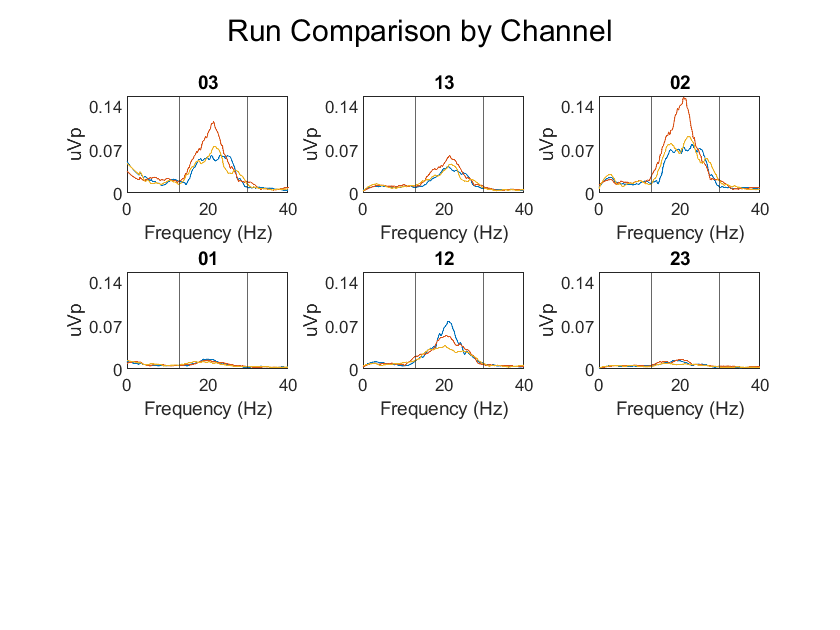

 %graphEachTrials(startindex, js, leng, channelsLeft, max(maxValuesLeft));
 figure; 
 graphEachTrials(startindex, js, leng, channelsRight, max(maxValuesRight));

## Fig2C 

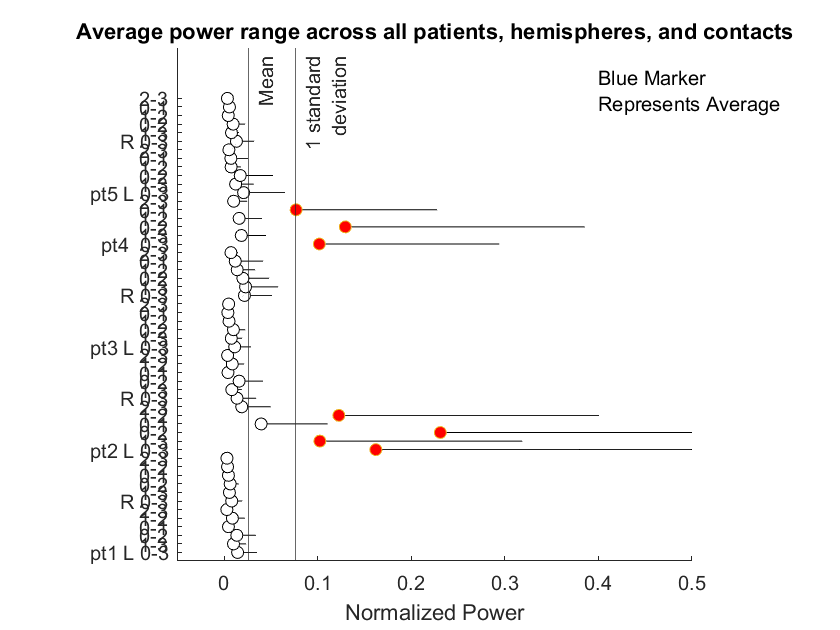

close all
dir = readtable("PtDirectorySimple.xlsx");
mastertable = []; 
%table with each run, contact, hemi and pt 
for i = 1:height(dir)
jsonFiles = dir.JsonSurvey{i};
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));
js = jsondecode(fileread(jsonFiles));
outTABLE = extractSurveyData(js, side, startIndex);
pt = repmat({append("pt", num)}, 18, 1); 
outTABLE.patient = pt; 
mastertable = [mastertable; outTABLE]; 
end 

localtab = [];  
y = zeros(4096,3); 
mastertable2 = mastertable;
col = []; 
%get only power data from mastertable
for x = 1:height(mastertable2) 
    temp = mastertable.PF_Data{x}; 
    col = [col; temp.Power]; 
end
%normalize and repack
normcol = normalize(col, 'range'); %pack into 0 to 1 
colm = reshape(col, 4096, height(mastertable2)); 

%put the normalized data into mastertable2 
for x = 1:height(mastertable)
    mastertable2.PF_Data{x}.Power = colm(:,x);
end

for k = 1:height(mastertable2)
    %if we have the first run then we have that contact 
    if mastertable2.RunNum(k) == 1 
        t = mastertable2(k:k+2, :); %get all three runs for that contact
        for j = 1:3
            powerdata = t.PF_Data{j};
            y(:,j) = powerdata.Power; 
            runav = mean(powerdata.Power);%single av for all power data
            runavmat(j) = runav; %store in matrix 
        end
        ny1 = y(:); %takes y and makes it a column vector 
        %ny2 = normalize(ny1, 'range'); %makes it 0 to 1 
        ny3 = reshape(ny1, size(y)); %takes normalized data and reshapes to y 
        ny3 = mean(ny3,2); 
        runavall = mean(ny3); %average the average of all three runs, single number
        runst = std(ny3); %std dev of all three runs 
        new = mastertable(k, :); 
        new.PF_Data = []; 
        new.RunNum = []; 
        new.RunAvg = runavall; 
        new.RunStd = runst; 
        %new.avpwrdata = array2table(y); 
        localtab = [localtab; new];
        
    end
end

%fix the ID categories for yticks 
nameparts = cell(height(localtab), 3);
name = cell(height(localtab), 1);
for i = 1:height(localtab)
    oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'};
    newchar = {''};
    oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'};
    newnum = {'0', '1', '2', '3'};
    nameparts{i,1} = replace(localtab.ChanID{i}, oldchar, newchar);
    nameparts{i,1} = replace(nameparts{i,1}, oldnum, newnum);
    nameparts{i,1} = append((nameparts{i,1}(1)), '-', (nameparts{i,1}(2))); 
    
    
    oldchar = {'LEFT', 'RIGHT'}; 
    newchar = {'L', 'R'};
    nameparts{i,2} = replace(localtab.SideID{i}, oldchar, newchar);
    
    nameparts{i,3} = localtab.patient{i}; 
    
    name{i,1} = append(nameparts{i,3}, ' ', nameparts{i,2}, ' ', nameparts{i,1});
end

ptnames = unique(cellstr(nameparts(:, 3)), 'stable'); 

for i = 1:height(nameparts)
    %if add pt 
    if ~ismember(i, ptindex)
        nameparts{i, 3} = ''; 
    end
    if ~ismember(i, sideindex)
        nameparts{i, 2} = ''; 
    end
name{i,1} = append(nameparts{i,3}, ' ', nameparts{i,2}, ' ', nameparts{i,1});
    %put it all together 
end

avarray = localtab.RunAvg; 
allmean = mean(avarray);
starray = localtab.RunStd; 
allstd = mean(starray);
minarray = avarray - starray; 
maxarray = avarray + starray; 
%find which means exceed 1 std 
avarray_more = avarray(avarray>(allmean+allstd));
indicies = find(avarray>(allmean+allstd)); 

y = [1:height(localtab); 1:height(localtab)]; 
x = transpose([avarray, maxarray]); 
line(x,y, 'color', 'k', 'LineWidth', 0.5)
hold on
plot(avarray, y, 'Marker',"o", 'MarkerFaceColor', 'white', 'MarkerEdgeColor', 'black', 'LineStyle',"none")
hold on
plot(avarray_more, indicies, 'Marker',"o", 'MarkerFaceColor', 'red', 'LineStyle',"none")
xlim([-0.05 0.5])
xline(allmean+allstd, '-', {'1 standard'; 'deviation'}) %label this 
%xline(allmean+2*allstd, '-', {'2sigma'})
xline(allmean, '-', {'Mean'})
xlabel("Normalized Power")
title("Average power range across all patients, hemispheres, and contacts")
text(0.4, 55, {'Blue Marker', 'Represents Average'})
sum(allmean+allstd<maxarray); 
set(gca,'ytick',[1:height(localtab)],'yticklabel',name); 
axis square

## Fig3 

oneChanStatsLoc compiles all the run data and normalizes the values using by doing abs(log10(value) and then downsamples 

this then gets normalized in a histogram 

RUN THIS FIRST :) 

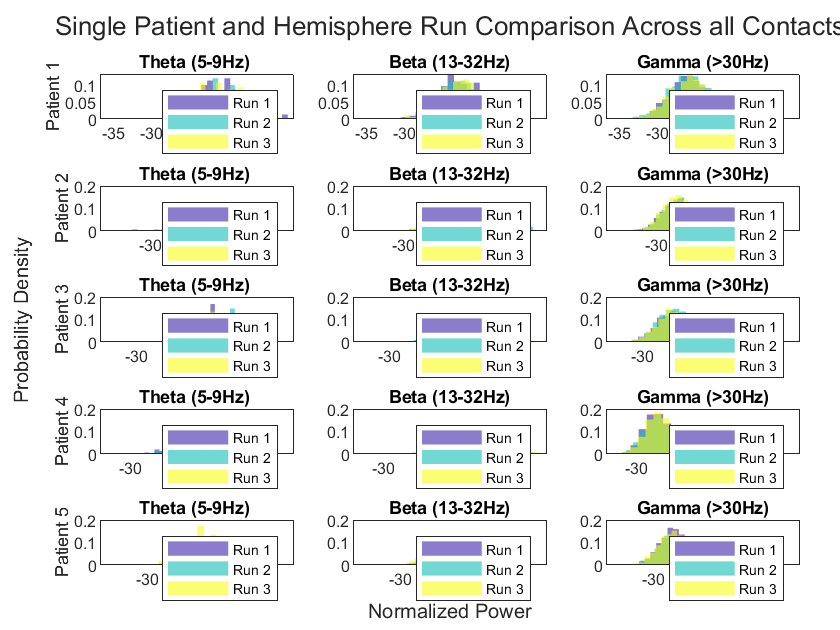

%histogram can take matrix but makes it a column vector :)
close all
dir = readtable("PtDirectorySimple.xlsx");
mastertable = []; 
%table with each run, contact, hemi and pt 
for i = 1:height(dir)
jsonFiles = dir.JsonSurvey{i};
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));
js = jsondecode(fileread(jsonFiles));
outTABLE = extractSurveyData(js, side, startIndex);
pt = repmat({append("pt", num)}, 18, 1); 
outTABLE.patient = pt; 
mastertable = [mastertable; outTABLE]; 
end 
%get just 1 hemi %in this case, pt5 right 
data = mastertable(contains(mastertable.SideID, 'RIGHT'), :); 
data = data(contains(cellstr(data.patient), 'pt1'), :); 

cmap = parula; 
cmapindex = round(linspace(1,256,3)); %gets 5 equally spaced poitns within perula 
r1color = cmap(cmapindex(1), :); %gets the RGB for the first color from cmapindex 
r2color = cmap(cmapindex(2), :);
r3color = cmap(cmapindex(3), :);
numbin = 20; 


ptindex = unique(cellstr(mastertable.patient)); 
t = tiledlayout(length(ptindex),3);  

for i = 1:length(ptindex) 
    
data = mastertable(contains(mastertable.SideID, 'RIGHT'), :); 
data = data(contains(cellstr(data.patient), ptindex(i)), :); 
    
%theta %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
t_r1 = oneChanStatsLoc(data, 4, 10, 0.25, 1); 
t_r2 = oneChanStatsLoc(data, 4, 10, 0.25, 2); 
t_r3 = oneChanStatsLoc(data, 4, 10, 0.25, 3); 

ax1 = nexttile; 
makeHistogram(t_r1, t_r2, t_r3, numbin, r1color, r2color, r3color)
title(append("Theta (5-9Hz) "))
pt_title = replace(ptindex(i), "pt", "Patient "); 
ylabel(pt_title)
%yticks([0 0.06 0.12])

%beta %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
b_r1 = oneChanStatsLoc(data, 12, 33, 0.25, 1); 
b_r2 = oneChanStatsLoc(data, 12, 33, 0.25, 2); 
b_r3 = oneChanStatsLoc(data, 12, 33, 0.25, 3);  

ax2 = nexttile; 
makeHistogram(b_r1, b_r2, b_r3, numbin, r1color, r2color, r3color)
title("Beta (13-32Hz)")
%yticks([0 0.07 0.14])

%gamma %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
g_r1 = oneChanStatsLoc(data, 30, 100, 0.25, 1); 
g_r2 = oneChanStatsLoc(data, 30, 100, 0.25, 2); 
g_r3 = oneChanStatsLoc(data, 30, 100, 0.25, 3); 

ax3 = nexttile; 
makeHistogram(g_r1, g_r2, g_r3, numbin, r1color, r2color, r3color)
title("Gamma (>30Hz)")

% t.XLabel.VerticalAlignment = 'cap'; 
linkaxes([ax1 ax2 ax3],'xy') 
end  
%total changes
t.Padding = 'compact'; 
xlabel(t, 'Normalized Power', 'FontSize', 10)
ylabel(t, 'Probability Density', 'FontSize', 10)
title(t, 'Single Patient and Hemisphere Run Comparison Across all Contacts')

## Fig4 beta 

contact agnostic file 

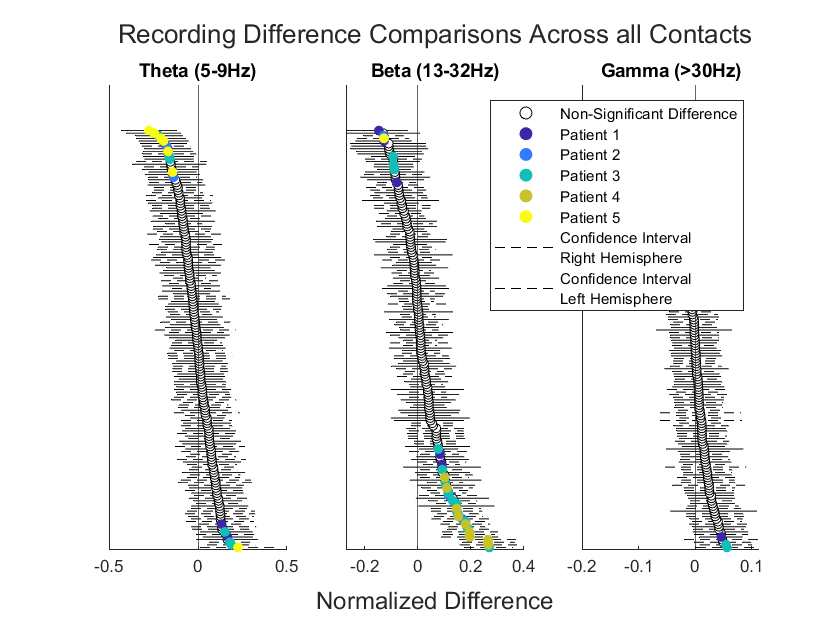

t = tiledlayout(1,3); 
%%%%%%%Theta%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
nexttile 
data = readtable("thetataballcontact_new.xlsx"); 
data2 = data(contains(data.Group, 'minus'), :); %all data 
data3 = data2(data2.Sig == 1, :); %anything significant 
indicies = find(data2.Sig == 1); 

%fix the ID categories for yticks 
nameparts = cell(height(data2), 3);
name = cell(height(data2), 1);
for i = 1:height(data2)
    oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'};
    newchar = {''};
    oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'};
    newnum = {'0', '1', '2', '3'};
    nameparts{i,1} = replace(data2.Chan{i}, oldchar, newchar);
    nameparts{i,1} = replace(nameparts{i,1}, oldnum, newnum);
        
    %take the patients category and put the different names in the
    %whereever 
    if contains(data2.Patients{i}, 'LEFT')
        nameparts{i,2} = 'L'; 
        nameparts{i,3} = data2.Patients{i}(1:3); 
    else
        nameparts{i,2} = 'R'; 
        nameparts{i,3} = data2.Patients{i}(1:3); 
    end
    
    name{i,1} = append(nameparts{i,3}, ' ', nameparts{i,2}, ' ', nameparts{i,1});
end

%close all 

%[~, y] = sort(table2array(sumTABLEp(1, :)), "descend"); %x is values in correct order %y is indicies %use tilde to suppress specific output
%y = [1:height(data2); 1:height(data2)]; 
datasort = sortrows(data2, 'Value', 'descend');
y = [1:height(data2); 1:height(data2)]; 
x = transpose([datasort.CIs_1, datasort.CIs_2]);
%line(x,y, 'color', 'k', 'LineWidth', 0.5)
hold on 

%color spacing 
cmap = parula; 
cmapindex = round(linspace(1,256,5)); %gets 5 equally spaced poitns within perula 
p1color = cmap(cmapindex(1), :); %gets the RGB for the first color from cmapindex 
p2color = cmap(cmapindex(2), :);  
p3color = cmap(cmapindex(3), :);  
p4color = cmap(cmapindex(4), :);  
p5color = cmap(cmapindex(5), :);  

%goal is to find where in data2 we find the information in pt1sig 
%aka where in data 2 do we have sig and pt1? 
data3 = sortrows(data3, 'Value', 'descend'); 
pt1sig = data3(contains(data3.Patients, 'pt1'), :); 
tfpt1 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt1')); 

pt2sig = data3(contains(data3.Patients, 'pt2'), :); 
tfpt2 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt2')); 

pt3sig = data3(contains(data3.Patients, 'pt3'), :); 
tfpt3 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt3')); 

pt4sig = data3(contains(data3.Patients, 'pt4'), :); 
tfpt4 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt4')); 

pt5sig = data3(contains(data3.Patients, 'pt5'), :); 
tfpt5 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt5')); 

%get the nonsig sorted values and their indicies
datasortnonsig = datasort(datasort.Sig == 0, :); 
y2 = find(datasort.Sig == 0); 

%this plots the data and the legend correctly updates with the correct
%marker 
hold on
a = 20; 
scatter(datasortnonsig.Value, y2, a, 'Marker', "o", 'MarkerFaceColor', "white", "MarkerEdgeColor", "black");    %do white circles  
scatter(pt1sig.Value, tfpt1, a, 'Marker',"o", "MarkerFaceColor", p1color, "MarkerEdgeColor", p1color); 
scatter(pt2sig.Value, tfpt2, a, 'Marker',"o", "MarkerFaceColor", p2color, "MarkerEdgeColor", p2color)
scatter(pt3sig.Value, tfpt3, a, 'Marker',"o", "MarkerFaceColor", p3color, "MarkerEdgeColor", p3color)
scatter(pt4sig.Value, tfpt4, a, 'Marker',"o", "MarkerFaceColor", p4color,  "MarkerEdgeColor", p4color)
scatter(pt5sig.Value, tfpt5, a, 'Marker',"o", "MarkerFaceColor", p5color, "MarkerEdgeColor", p5color)

%plot confidence intervals for left and right 
datasort_r = datasort(contains(datasort.Patients, 'RIGHT'), :); 
datasort_l = datasort(contains(datasort.Patients, 'LEFT'), :); 

yr = find(contains(datasort.Patients, 'RIGHT')); 
yr = [yr, yr]'; 
xr = transpose([datasort_r.CIs_1, datasort_r.CIs_2]);
plot(xr,yr, 'color', 'k', 'LineWidth', 0.5, 'LineStyle',"--")  

hold on
yl = find(contains(datasort.Patients, 'LEFT')); 
yl = [yl, yl]'; 
xl = transpose([datasort_l.CIs_1, datasort_l.CIs_2]);
plot(xl,yl, 'color', 'k', 'LineWidth', 0.5) 

xline(0) 
%l = legend({'Non-Significant Difference', 'Patient 1 ', 'Patient 2', 'Patient 3', 'Patient 4', 'Patient 5', 'CI Right', 'CI Left'}); 

%replot the markers to go over the lines while maintaining the legend
a = 20; 
scatter(datasortnonsig.Value, y2, a, 'Marker', "o", 'MarkerFaceColor', "white", "MarkerEdgeColor", "black");    %do white circles  
scatter(pt1sig.Value, tfpt1, a, 'Marker',"o", "MarkerFaceColor", p1color, "MarkerEdgeColor", p1color); 
scatter(pt2sig.Value, tfpt2, a, 'Marker',"o", "MarkerFaceColor", p2color, "MarkerEdgeColor", p2color)
scatter(pt3sig.Value, tfpt3, a, 'Marker',"o", "MarkerFaceColor", p3color, "MarkerEdgeColor", p3color)
scatter(pt4sig.Value, tfpt4, a, 'Marker',"o", "MarkerFaceColor", p4color,  "MarkerEdgeColor", p4color)
scatter(pt5sig.Value, tfpt5, a, 'Marker',"o", "MarkerFaceColor", p5color, "MarkerEdgeColor", p5color)

%l.String = {'Non-Significant Difference', 'Patient 1 ', 'Patient 2', 'Patient 3', 'Patient 4', 'Patient 5', 'Confidence Interval Right Hemisphere', 'Confidence Interval Left Hemisphere'}; 
title("Theta (5-9Hz)")
yticks([])
%xlabel("Normalized Difference")
%%%%Beta%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
data = readtable("betataballcontact_new.xlsx"); 
data2 = data(contains(data.Group, 'minus'), :); %all data 
data3 = data2(data2.Sig == 1, :); %anything significant 
indicies = find(data2.Sig == 1); 

%fix the ID categories for yticks 
nameparts = cell(height(data2), 3);
name = cell(height(data2), 1);
for i = 1:height(data2)
    oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'};
    newchar = {''};
    oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'};
    newnum = {'0', '1', '2', '3'};
    nameparts{i,1} = replace(data2.Chan{i}, oldchar, newchar);
    nameparts{i,1} = replace(nameparts{i,1}, oldnum, newnum);
        
    %take the patients category and put the different names in the
    %whereever 
    if contains(data2.Patients{i}, 'LEFT')
        nameparts{i,2} = 'L'; 
        nameparts{i,3} = data2.Patients{i}(1:3); 
    else
        nameparts{i,2} = 'R'; 
        nameparts{i,3} = data2.Patients{i}(1:3); 
    end
    
    name{i,1} = append(nameparts{i,3}, ' ', nameparts{i,2}, ' ', nameparts{i,1});
end

%close all 

%[~, y] = sort(table2array(sumTABLEp(1, :)), "descend"); %x is values in correct order %y is indicies %use tilde to suppress specific output
%y = [1:height(data2); 1:height(data2)]; 
nexttile 
datasort = sortrows(data2, 'Value', 'descend');
y = [1:height(data2); 1:height(data2)]; 
x = transpose([datasort.CIs_1, datasort.CIs_2]);
%line(x,y, 'color', 'k', 'LineWidth', 0.5)
hold on 

%color spacing 
cmap = parula; 
cmapindex = round(linspace(1,256,5)); %gets 5 equally spaced poitns within perula 
p1color = cmap(cmapindex(1), :); %gets the RGB for the first color from cmapindex 
p2color = cmap(cmapindex(2), :);  
p3color = cmap(cmapindex(3), :);  
p4color = cmap(cmapindex(4), :);  
p5color = cmap(cmapindex(5), :);  

%goal is to find where in data2 we find the information in pt1sig 
%aka where in data 2 do we have sig and pt1? 
data3 = sortrows(data3, 'Value', 'descend'); 
pt1sig = data3(contains(data3.Patients, 'pt1'), :); 
tfpt1 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt1')); 

pt2sig = data3(contains(data3.Patients, 'pt2'), :); 
tfpt2 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt2')); 

pt3sig = data3(contains(data3.Patients, 'pt3'), :); 
tfpt3 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt3')); 

pt4sig = data3(contains(data3.Patients, 'pt4'), :); 
tfpt4 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt4')); 

pt5sig = data3(contains(data3.Patients, 'pt5'), :); 
tfpt5 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt5')); 

%get the nonsig sorted values and their indicies
datasortnonsig = datasort(datasort.Sig == 0, :); 
y2 = find(datasort.Sig == 0); 

%this plots the data and the legend correctly updates with the correct
%marker 
hold on
a = 20; 
scatter(datasortnonsig.Value, y2, a, 'Marker', "o", 'MarkerFaceColor', "white", "MarkerEdgeColor", "black");    %do white circles  
scatter(pt1sig.Value, tfpt1, a, 'Marker',"o", "MarkerFaceColor", p1color, "MarkerEdgeColor", p1color); 
scatter(pt2sig.Value, tfpt2, a, 'Marker',"o", "MarkerFaceColor", p2color, "MarkerEdgeColor", p2color)
scatter(pt3sig.Value, tfpt3, a, 'Marker',"o", "MarkerFaceColor", p3color, "MarkerEdgeColor", p3color)
scatter(pt4sig.Value, tfpt4, a, 'Marker',"o", "MarkerFaceColor", p4color,  "MarkerEdgeColor", p4color)
scatter(pt5sig.Value, tfpt5, a, 'Marker',"o", "MarkerFaceColor", p5color, "MarkerEdgeColor", p5color)

%plot confidence intervals for left and right 
datasort_r = datasort(contains(datasort.Patients, 'RIGHT'), :); 
datasort_l = datasort(contains(datasort.Patients, 'LEFT'), :); 

yr = find(contains(datasort.Patients, 'RIGHT')); 
yr = [yr, yr]'; 
xr = transpose([datasort_r.CIs_1, datasort_r.CIs_2]);
plot(xr,yr, 'color', 'k', 'LineWidth', 0.5, 'LineStyle',"--")  

hold on
yl = find(contains(datasort.Patients, 'LEFT')); 
yl = [yl, yl]'; 
xl = transpose([datasort_l.CIs_1, datasort_l.CIs_2]);
plot(xl,yl, 'color', 'k', 'LineWidth', 0.5) 

xline(0) 
%l = legend({'Non-Significant Difference', 'Patient 1 ', 'Patient 2', 'Patient 3', 'Patient 4', 'Patient 5', 'CI Right', 'CI Left'}); 

% %replot the markers to go over the lines while maintaining the legend
a = 20; 
scatter(datasortnonsig.Value, y2, a, 'Marker', "o", 'MarkerFaceColor', "white", "MarkerEdgeColor", "black");    %do white circles  
scatter(pt1sig.Value, tfpt1, a, 'Marker',"o", "MarkerFaceColor", p1color, "MarkerEdgeColor", p1color); 
scatter(pt2sig.Value, tfpt2, a, 'Marker',"o", "MarkerFaceColor", p2color, "MarkerEdgeColor", p2color)
scatter(pt3sig.Value, tfpt3, a, 'Marker',"o", "MarkerFaceColor", p3color, "MarkerEdgeColor", p3color)
scatter(pt4sig.Value, tfpt4, a, 'Marker',"o", "MarkerFaceColor", p4color,  "MarkerEdgeColor", p4color)
scatter(pt5sig.Value, tfpt5, a, 'Marker',"o", "MarkerFaceColor", p5color, "MarkerEdgeColor", p5color)

%l.String = {'Non-Significant Difference', 'Patient 1 ', 'Patient 2', 'Patient 3', 'Patient 4', 'Patient 5', 'Confidence Interval Right Hemisphere', 'Confidence Interval Left Hemisphere'}; 
title("Beta (13-32Hz)")
yticks([])
%xlabel("Normalized Difference")
%axis square

%%%%Gamma%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

nexttile
data = readtable("gammataballcontact_new.xlsx"); 
data2 = data(contains(data.Group, 'minus'), :); %all data 
data3 = data2(data2.Sig == 1, :); %anything significant 
indicies = find(data2.Sig == 1); 

%fix the ID categories for yticks 
nameparts = cell(height(data2), 3);
name = cell(height(data2), 1);
for i = 1:height(data2)
    oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'};
    newchar = {''};
    oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'};
    newnum = {'0', '1', '2', '3'};
    nameparts{i,1} = replace(data2.Chan{i}, oldchar, newchar);
    nameparts{i,1} = replace(nameparts{i,1}, oldnum, newnum);
        
    %take the patients category and put the different names in the
    %whereever 
    if contains(data2.Patients{i}, 'LEFT')
        nameparts{i,2} = 'L'; 
        nameparts{i,3} = data2.Patients{i}(1:3); 
    else
        nameparts{i,2} = 'R'; 
        nameparts{i,3} = data2.Patients{i}(1:3); 
    end
    
    name{i,1} = append(nameparts{i,3}, ' ', nameparts{i,2}, ' ', nameparts{i,1});
end

%close all 

%[~, y] = sort(table2array(sumTABLEp(1, :)), "descend"); %x is values in correct order %y is indicies %use tilde to suppress specific output
%y = [1:height(data2); 1:height(data2)]; 
datasort = sortrows(data2, 'Value', 'descend');
y = [1:height(data2); 1:height(data2)]; 
x = transpose([datasort.CIs_1, datasort.CIs_2]);
%line(x,y, 'color', 'k', 'LineWidth', 0.5)
hold on 

%color spacing 
cmap = parula; 
cmapindex = round(linspace(1,256,5)); %gets 5 equally spaced poitns within perula 
p1color = cmap(cmapindex(1), :); %gets the RGB for the first color from cmapindex 
p2color = cmap(cmapindex(2), :);  
p3color = cmap(cmapindex(3), :);  
p4color = cmap(cmapindex(4), :);  
p5color = cmap(cmapindex(5), :);  

%goal is to find where in data2 we find the information in pt1sig 
%aka where in data 2 do we have sig and pt1? 
data3 = sortrows(data3, 'Value', 'descend'); 
pt1sig = data3(contains(data3.Patients, 'pt1'), :); 
tfpt1 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt1')); 

pt2sig = data3(contains(data3.Patients, 'pt2'), :); 
tfpt2 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt2')); 

pt3sig = data3(contains(data3.Patients, 'pt3'), :); 
tfpt3 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt3')); 

pt4sig = data3(contains(data3.Patients, 'pt4'), :); 
tfpt4 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt4')); 

pt5sig = data3(contains(data3.Patients, 'pt5'), :); 
tfpt5 = find(datasort.Sig == 1 & contains(datasort.Patients, 'pt5')); 

%get the nonsig sorted values and their indicies
datasortnonsig = datasort(datasort.Sig == 0, :); 
y2 = find(datasort.Sig == 0); 

%this plots the data and the legend correctly updates with the correct
%marker 
hold on
a = 20; 
scatter(datasortnonsig.Value, y2, a, 'Marker', "o", 'MarkerFaceColor', "white", "MarkerEdgeColor", "black");    %do white circles  
scatter(pt1sig.Value, tfpt1, a, 'Marker',"o", "MarkerFaceColor", p1color, "MarkerEdgeColor", p1color); 
scatter(pt2sig.Value, tfpt2, a, 'Marker',"o", "MarkerFaceColor", p2color, "MarkerEdgeColor", p2color)
scatter(pt3sig.Value, tfpt3, a, 'Marker',"o", "MarkerFaceColor", p3color, "MarkerEdgeColor", p3color)
scatter(pt4sig.Value, tfpt4, a, 'Marker',"o", "MarkerFaceColor", p4color,  "MarkerEdgeColor", p4color)
scatter(pt5sig.Value, tfpt5, a, 'Marker',"o", "MarkerFaceColor", p5color, "MarkerEdgeColor", p5color)

%plot confidence intervals for left and right 
datasort_r = datasort(contains(datasort.Patients, 'RIGHT'), :); 
datasort_l = datasort(contains(datasort.Patients, 'LEFT'), :); 

yr = find(contains(datasort.Patients, 'RIGHT')); 
yr = [yr, yr]'; 
xr = transpose([datasort_r.CIs_1, datasort_r.CIs_2]);
plot(xr,yr, 'color', 'k', 'LineWidth', 0.5, 'LineStyle',"--")  

hold on
yl = find(contains(datasort.Patients, 'LEFT')); 
yl = [yl, yl]'; 
xl = transpose([datasort_l.CIs_1, datasort_l.CIs_2]);
plot(xl,yl, 'color', 'k', 'LineWidth', 0.5) 

xline(0) 
l = legend({'Non-Significant Difference', 'Patient 1 ', 'Patient 2', 'Patient 3', 'Patient 4', 'Patient 5', 'CI Right', 'CI Left'}); 

%replot the markers to go over the lines while maintaining the legend
a = 20; 
scatter(datasortnonsig.Value, y2, a, 'Marker', "o", 'MarkerFaceColor', "white", "MarkerEdgeColor", "black");    %do white circles  
scatter(pt1sig.Value, tfpt1, a, 'Marker',"o", "MarkerFaceColor", p1color, "MarkerEdgeColor", p1color); 
scatter(pt2sig.Value, tfpt2, a, 'Marker',"o", "MarkerFaceColor", p2color, "MarkerEdgeColor", p2color)
scatter(pt3sig.Value, tfpt3, a, 'Marker',"o", "MarkerFaceColor", p3color, "MarkerEdgeColor", p3color)
scatter(pt4sig.Value, tfpt4, a, 'Marker',"o", "MarkerFaceColor", p4color,  "MarkerEdgeColor", p4color)
scatter(pt5sig.Value, tfpt5, a, 'Marker',"o", "MarkerFaceColor", p5color, "MarkerEdgeColor", p5color)

l.String = {'Non-Significant Difference', 'Patient 1 ', 'Patient 2', 'Patient 3', 'Patient 4', 'Patient 5', strcat('Confidence Interval', string(newline), 'Right Hemisphere'), strcat('Confidence Interval', string(newline), 'Left Hemisphere')}; 
l.Location = 'northeast'; 
title("Gamma (>30Hz)")
yticks([])
%xlabel("Normalized Difference")
xlabel(t, "Normalized Difference")
title(t,"Recording Difference Comparisons Across all Contacts");

## Fig 4b 

graph showing sig run fraction per patient 

data = readtable("thetataballcontact.xlsx"); 
data2 = data(contains(data.Group, 'minus'), :); %all data 
data3 = data2(data2.Sig == 1, :); %anything significant 
indicies = find(data2.Sig == 1); 



cmap = parula; 
cmapindex = round(linspace(1,256,5)); %gets 5 equally spaced poitns within perula 
p1color = cmap(cmapindex(1), :); %gets the RGB for the first color from cmapindex 
p2color = cmap(cmapindex(2), :);  
p3color = cmap(cmapindex(3), :);  
p4color = cmap(cmapindex(4), :);  
p5color = cmap(cmapindex(5), :);  

x = categorical({'A', 'B', 'C', 'D', 'E', 'F', 'G', 'H', 'I'}); 
y = repmat(100, 1,9); 
b1 = bar(x,y); %make the background 

Error using bar (line 213)
Data inputs must match the axis configuration. A numeric axis must have numeric data inputs or data inputs which can be converted to double.

b1.FaceColor = [ 1 1 1]; 
y1 = repmat(10, 1, 9); 
hold on 
b =bar (x, y1); 
b.FaceColor = 'flat'; 
%PT1
b.CData(1,:) = p1color; 
b.CData(2,:) = p1color; 
%PT2
b.CData(3,:) = p2color; 
b.CData(4,:) = p2color; 
%PT3
b.CData(5,:) = p3color; 
b.CData(6,:) = p3color; 
%PT4
b.CData(7,:) = p4color; 
%PT5
b.CData(8,:) = p5color; 
b.CData(9,:) = p5color; 
xlabel("Patient And Hemisphere")
ylabel("Fraction of Significant Differences")


function [] = makeHistogram(t_r1, t_r2, t_r3, numbin, r1color, r2color, r3color)
h1 = histogram(t_r1);
hold on
h2 = histogram(t_r2);
hold on
h3 = histogram(t_r3);
h1.Normalization = 'probability';
h2.Normalization = 'probability';
h3.Normalization = 'probability';         
h1.NumBins = numbin;
h2.NumBins = numbin; 
h3.NumBins = numbin;  
h1.EdgeColor = 'none'; 
h2.EdgeColor = 'none'; 
h3.EdgeColor = 'none'; 
h1.FaceColor = r1color; 
h2.FaceColor = r2color; 
h3.FaceColor = r3color;
legend({'Run 1', 'Run 2', 'Run 3'})
%axis square
end


function [oneChan] = oneChanStatsLoc(outTABLE, flb, fub, res, run) 
%take all contact and runs for one hemi 
%standardize values and downsample 
%get all the data for one run across all channels 

% runs = zeros(82,3);
% ids = cell(82,3);
%chop larger table to just channel of interest 
%imported value based upon what we choose lmoa 
z = fub - flb; %define length of frequency range 
z = z * 1/res; %get the length of the vector we WANT 
%length * amount of samples per second 

dummy = outTABLE.PF_Data{1}; %arbitrary data 
ffreq = dummy.Frequency > flb & dummy.Frequency < fub; %find frequency
fpwr = dummy.Power(ffreq); %find power within that frequency
dwnsamp = round(length(fpwr) / z); %vector length we have / vector length we want

%break table into just run of interest from input arg 
temp = outTABLE(outTABLE.RunNum == run, :); 

for i = 1:height(temp)
powerdata = temp.PF_Data{i};
%find freq vales of interest
fbeta = powerdata.Frequency > flb & powerdata.Frequency < fub;
betapwr = powerdata.Power(fbeta);
%FIXED ON 6/21, switched order of log10 and abs 
betapwr = 10*(log10(betapwr));
%betapwr = downsample(betapwr, dwnsamp);
x = length(betapwr); 
if i == 1 
    runs = zeros(x,6);
end 

runs(:,i) = betapwr;  
end 

runs = runs(:); 
runs = downsample(runs, dwnsamp);
oneChan = runs; 
end 